# Compare the PC of the data with the fluorophore basis

We searched for two basis sets for the fluorescent data from the lip and tongue.  We are exploring the data with an excitation light of 415 nm.

This script does the same analysis as s_oeDimensionality56, but for the wavelength range from 500-700nm.

**Analysis from 500-700nm**

- From 500-700nm **3 basis functions fit the tongue data and the lip data**, separately.

- To fit the lip data from the tongue data, **we need to use 5 or 6 tongue** dimensions.  We think the tongue dimensions emphasize fitting all the variance in 600-700, and thus we need to go further pick up any benefit for the lip - where all the variance is in 500-600nm.

- To fit the tongue data from the lip data is **impossible**.  The lip data has no components that could represent the porphyrin and chlorphyll found on the tongue.

(See s_oeDimensionality56 for the tissue optics calculation we tried.)

## Initialize the database and ISET

ieInit;

% Wavelength samples
waves = 500:700;

% Read in the database
[T,dataDir] = oeDatabaseCreate;

% Normalize for unit length, using oeReadFiles.
normalizationP = 520;

% This checks the quality of the fit of the data.
dimensionality = [2 3 4 5];


## Read the tongue data

We tried various normalization approaches.  They are all the same.  

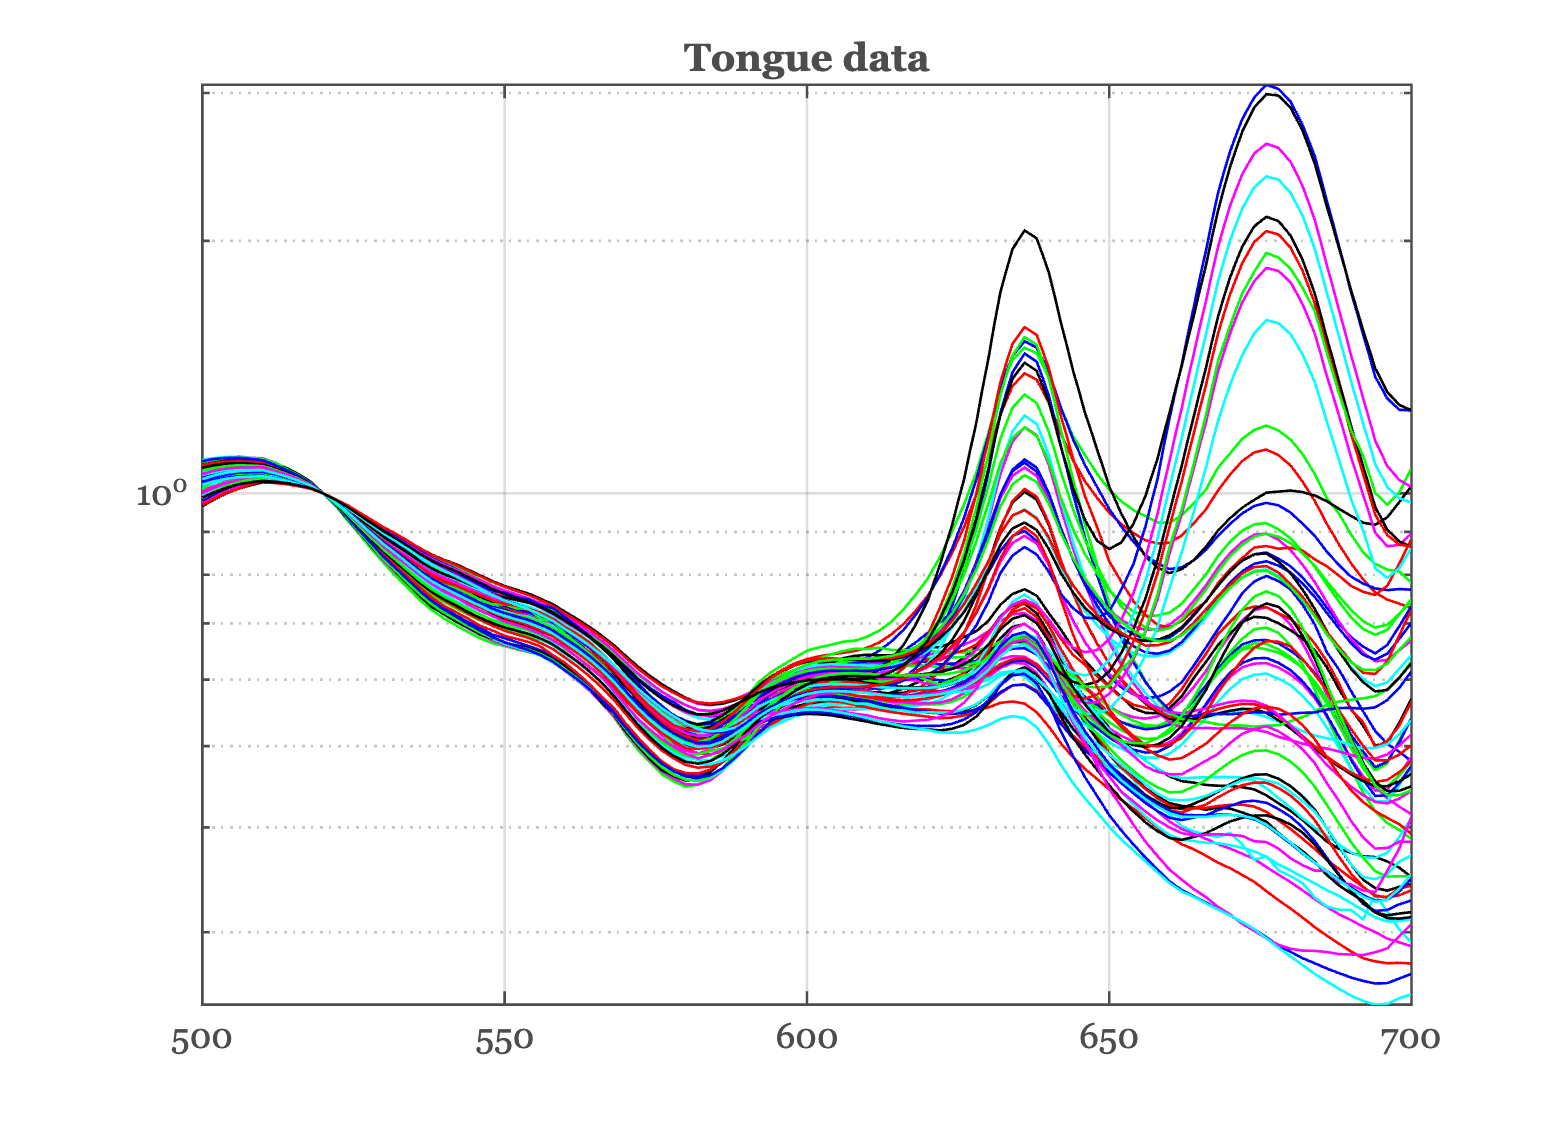

files405 = ieTableGet(T,...
    'ewave',405, ...
    'substrate','tongue');
files415 = ieTableGet(T,...
    'ewave',415, ...
    'substrate','tongue');
filesAll = cat(1,files405,files415);

dataTongue = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);

ieFigure;
semilogy(waves,dataTongue);
grid on;
title('Tongue data');

## Set the dimensionality of the tongue data

Perform SVD explicitly, rather than using the pca() method.

[UT, ~, ~] = svd(dataTongue, 'econ');

## Build the basis

We start with four fluorophores and in the search process we attenuate the collagen with a blood estimate and we add keratin as a 5th fluorophore.

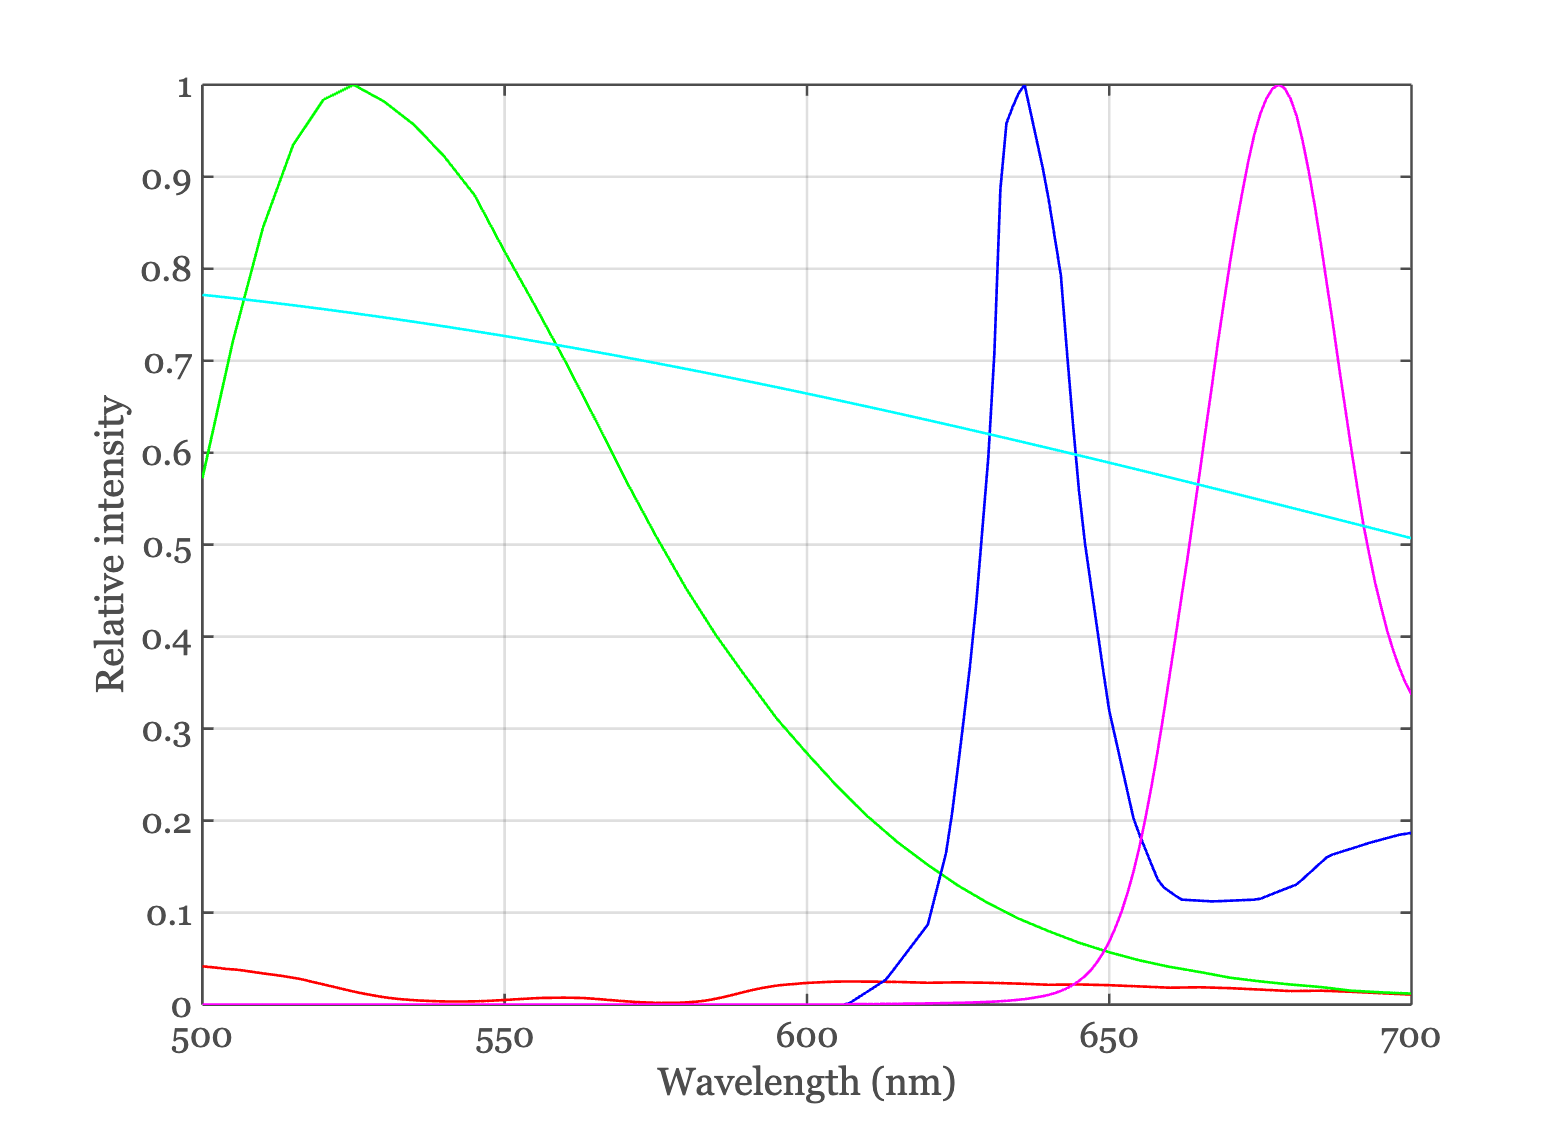

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor','PorphyrinBjurshammar','chlorophyllA-7'};
fixedFluorophores = fiLoadBasis(fluorophoreNamesB,'wave',waves);
[global_params, weights, finalFluorophores] = oeSolveJoint(waves, dataTongue, fixedFluorophores);

ieFigure;
plot(waves,finalFluorophores);
grid on; xlabel('Wavelength (nm)'); ylabel('Relative intensity');

## Fit 5 finalFluorophores from PCA (UT)

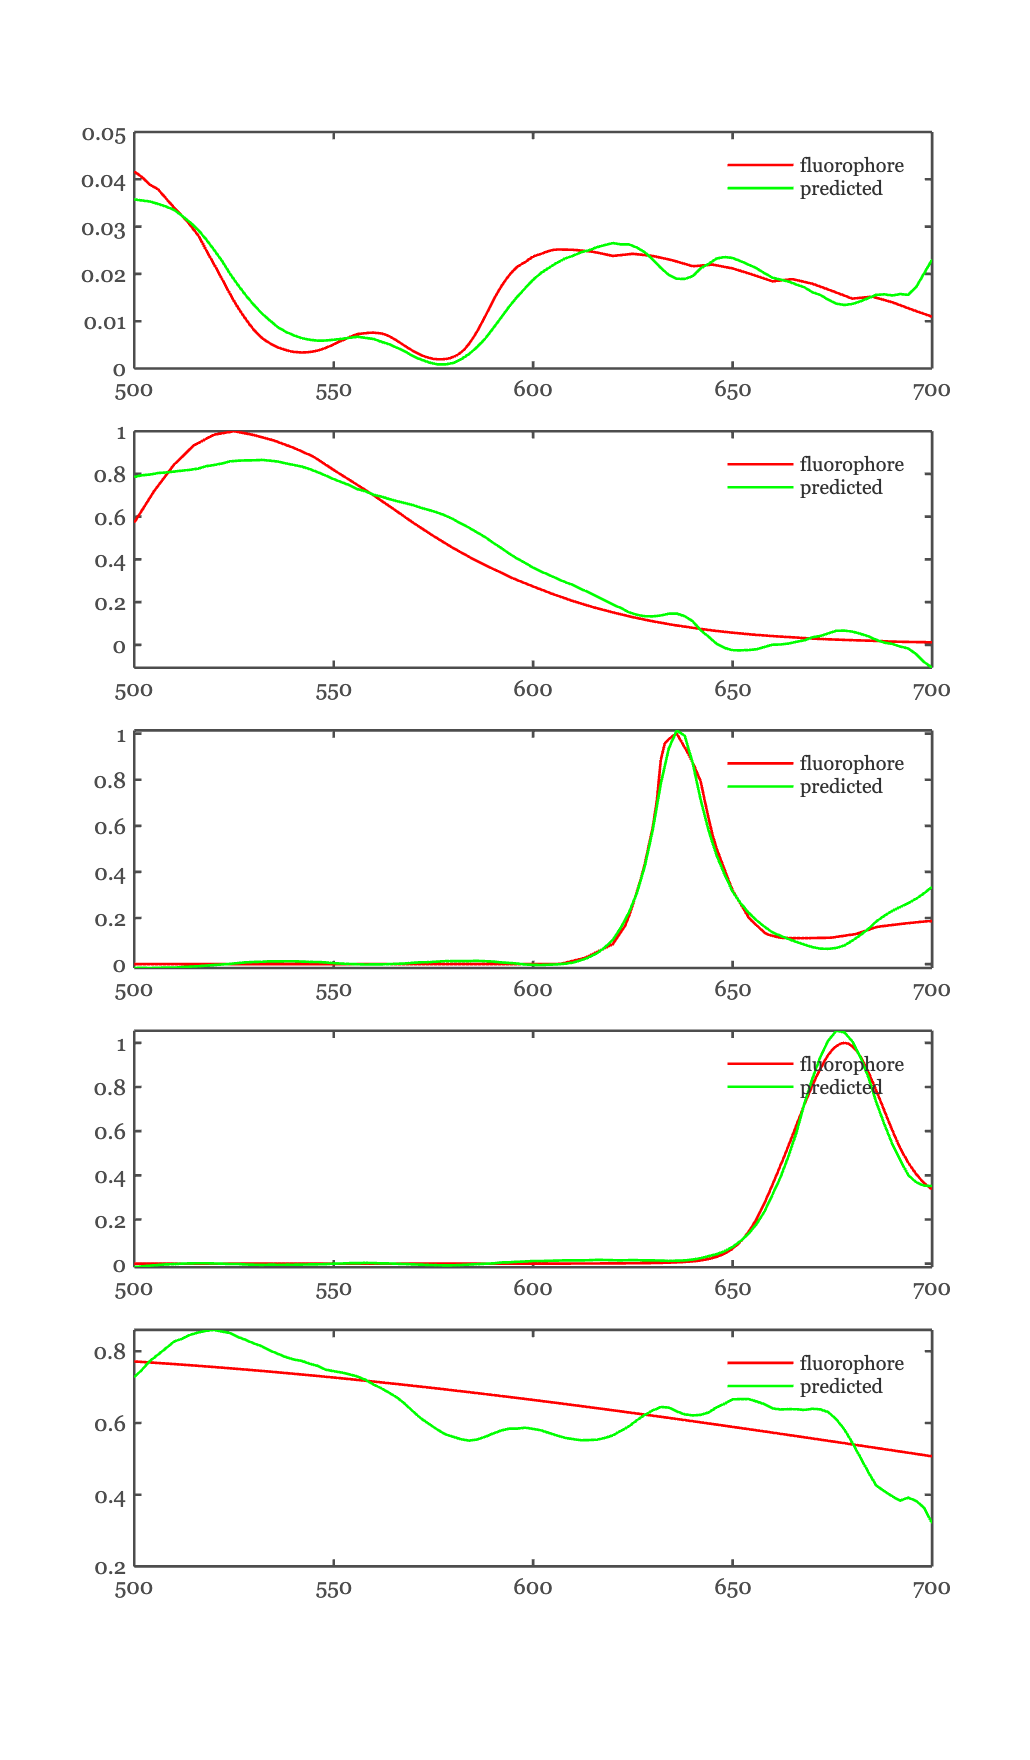

nDim = 5;   % How many PCs to fit the fluorophores?
nFluorophores = 5;
x = UT(:,1:nDim)'*finalFluorophores;
predicted = UT(:,1:nDim)*x;
ieFigure([],'tall');
tiledlayout(nFluorophores,1);
for ii = 1:nFluorophores
    nexttile;
    plot(waves,finalFluorophores(:,ii),waves,predicted(:,ii));
    legend({'fluorophore','predicted'});
end

## Read the Lip data

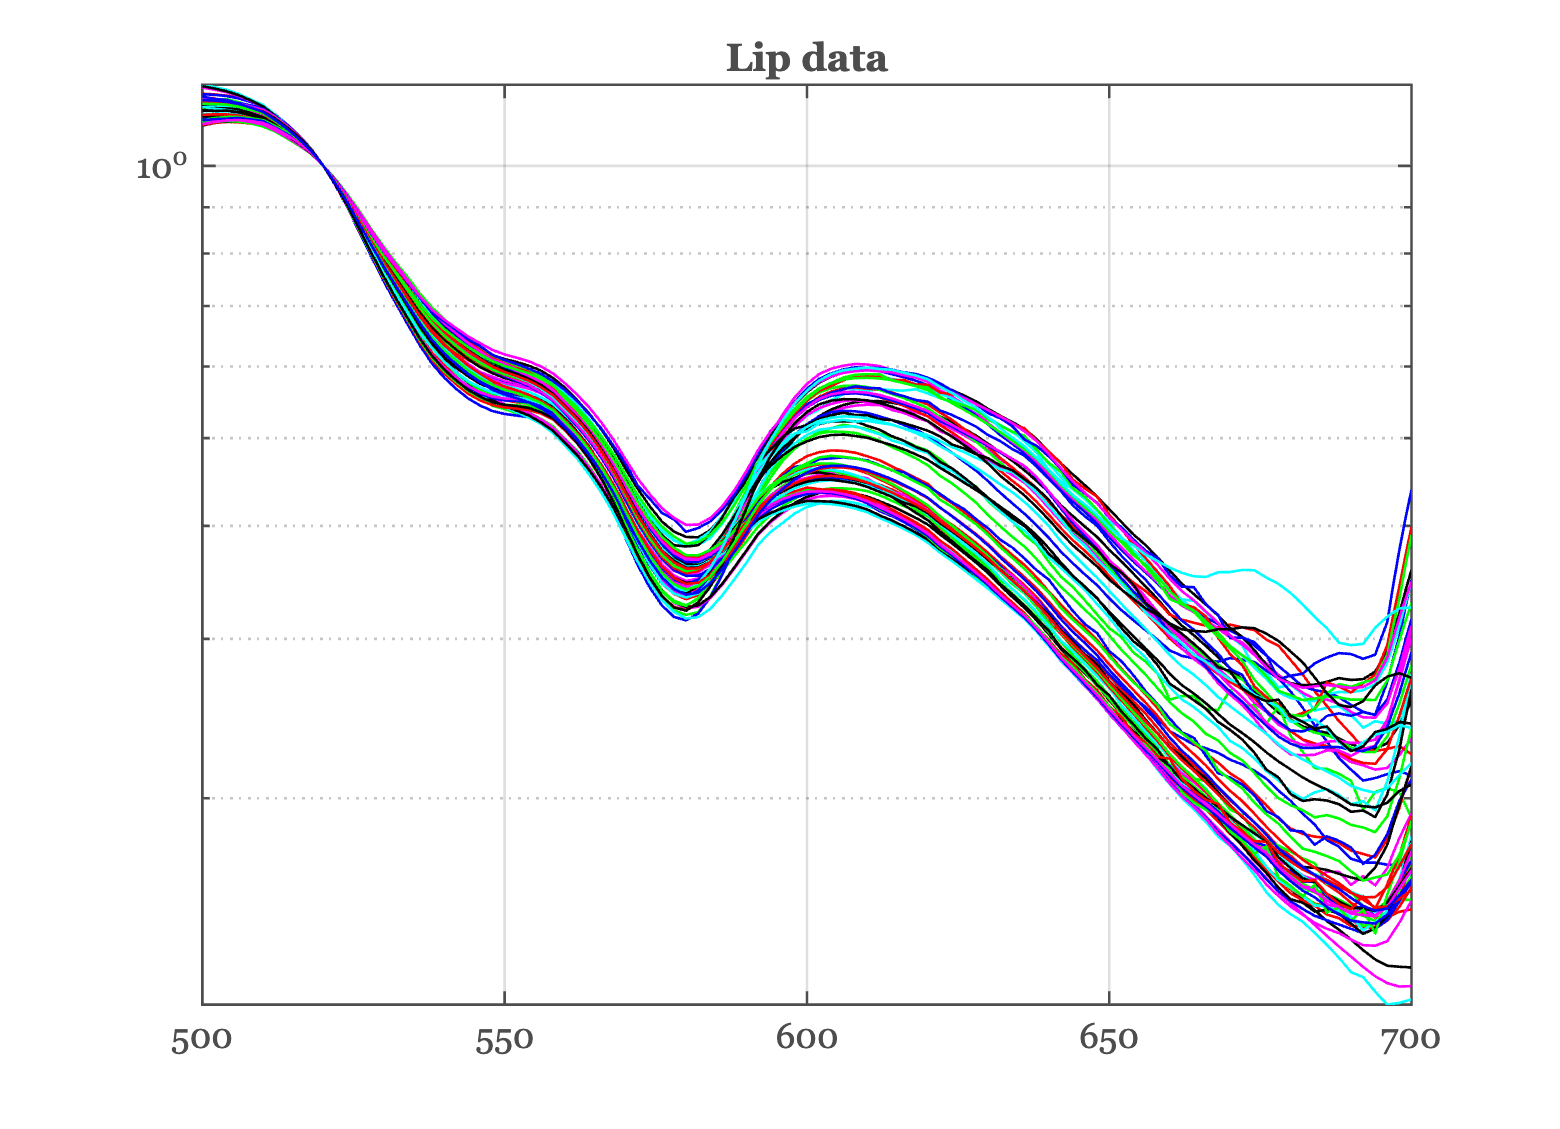

files405 = ieTableGet(T,...
    'ewave',405, ...
    'substrate','lip');
files415 = ieTableGet(T,...
    'ewave',415, ...
    'substrate','lip');
filesAll = cat(1,files405,files415);
dataLip = oeReadFiles(filesAll,'waves',waves,'normalized wave',normalizationP);

ieFigure;
semilogy(waves,dataLip);
grid on;
title('Lip data');

## Find the lip bases

[UL, S, ~] = svd(dataLip, 'econ');

## Fluorophores for the lip

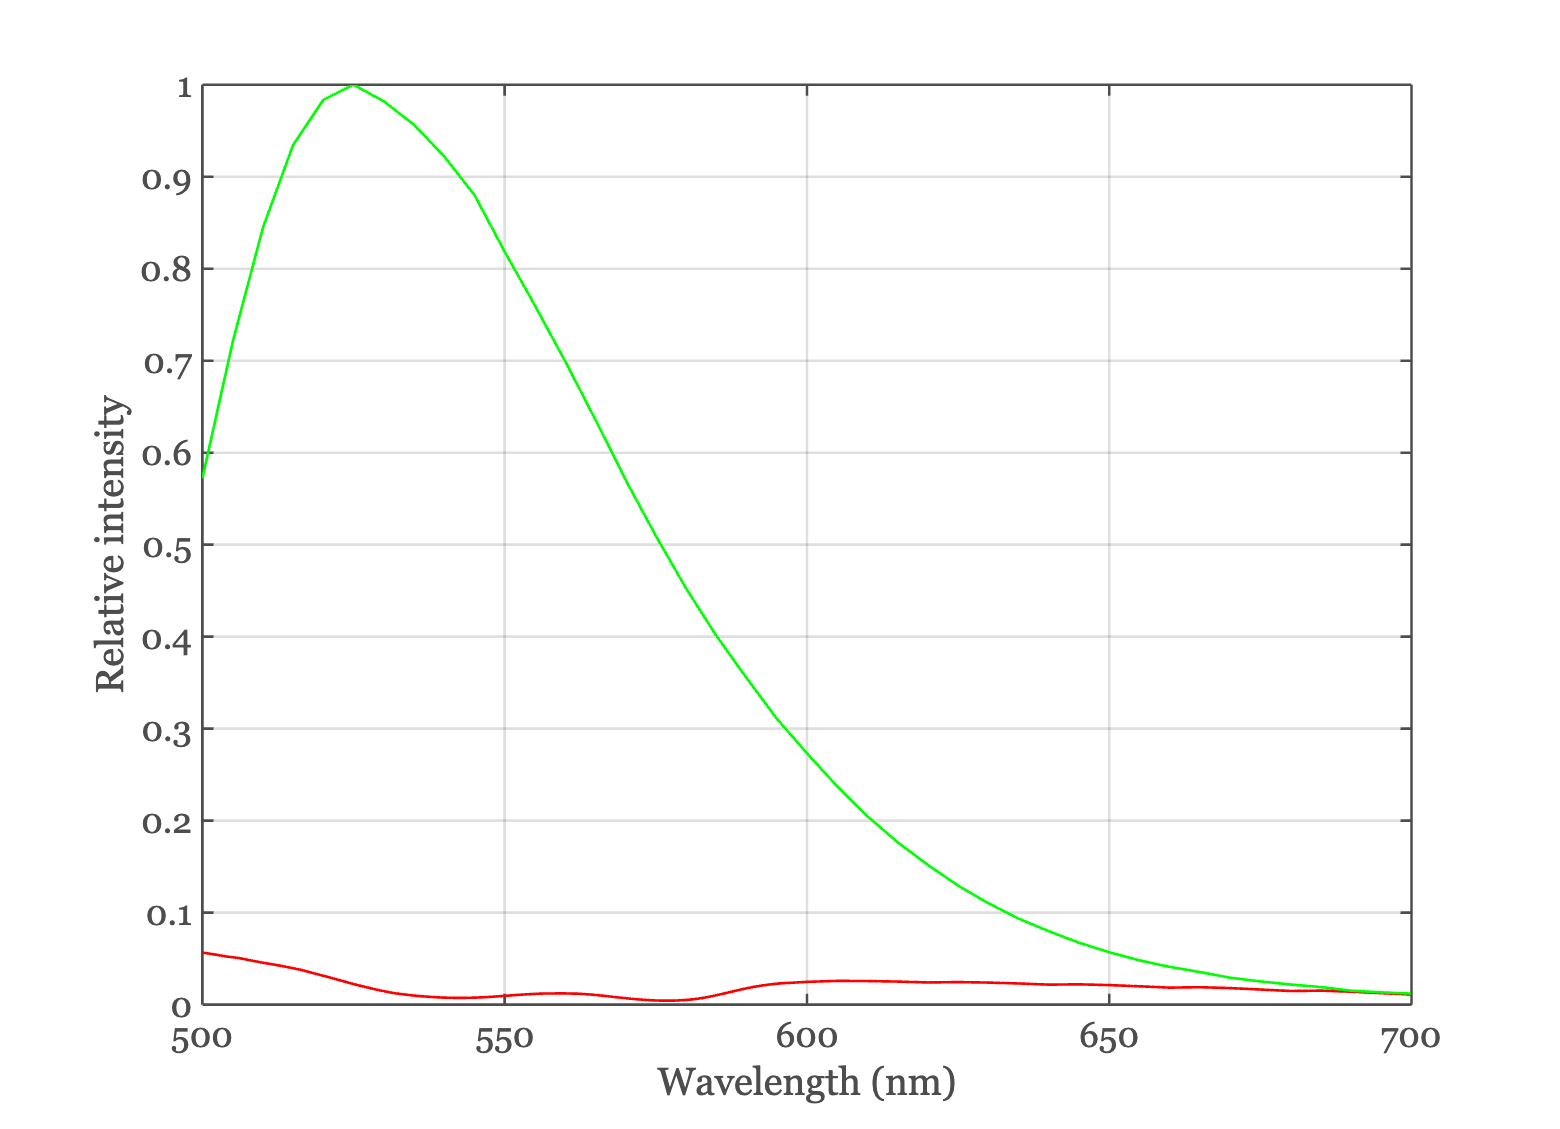

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor'};
[fixedFluorophores,wave] = fiLoadBasis(fluorophoreNamesB,'wave',waves);
[odLip,weights,finalFluorophores] = oeSolveBlood(waves,dataLip,fixedFluorophores(:,1:2));

ieFigure;
plot(waves,finalFluorophores);
grid on; xlabel('Wavelength (nm)'); ylabel('Relative intensity');

## Fit 2 final fluorophores with the lip PCs

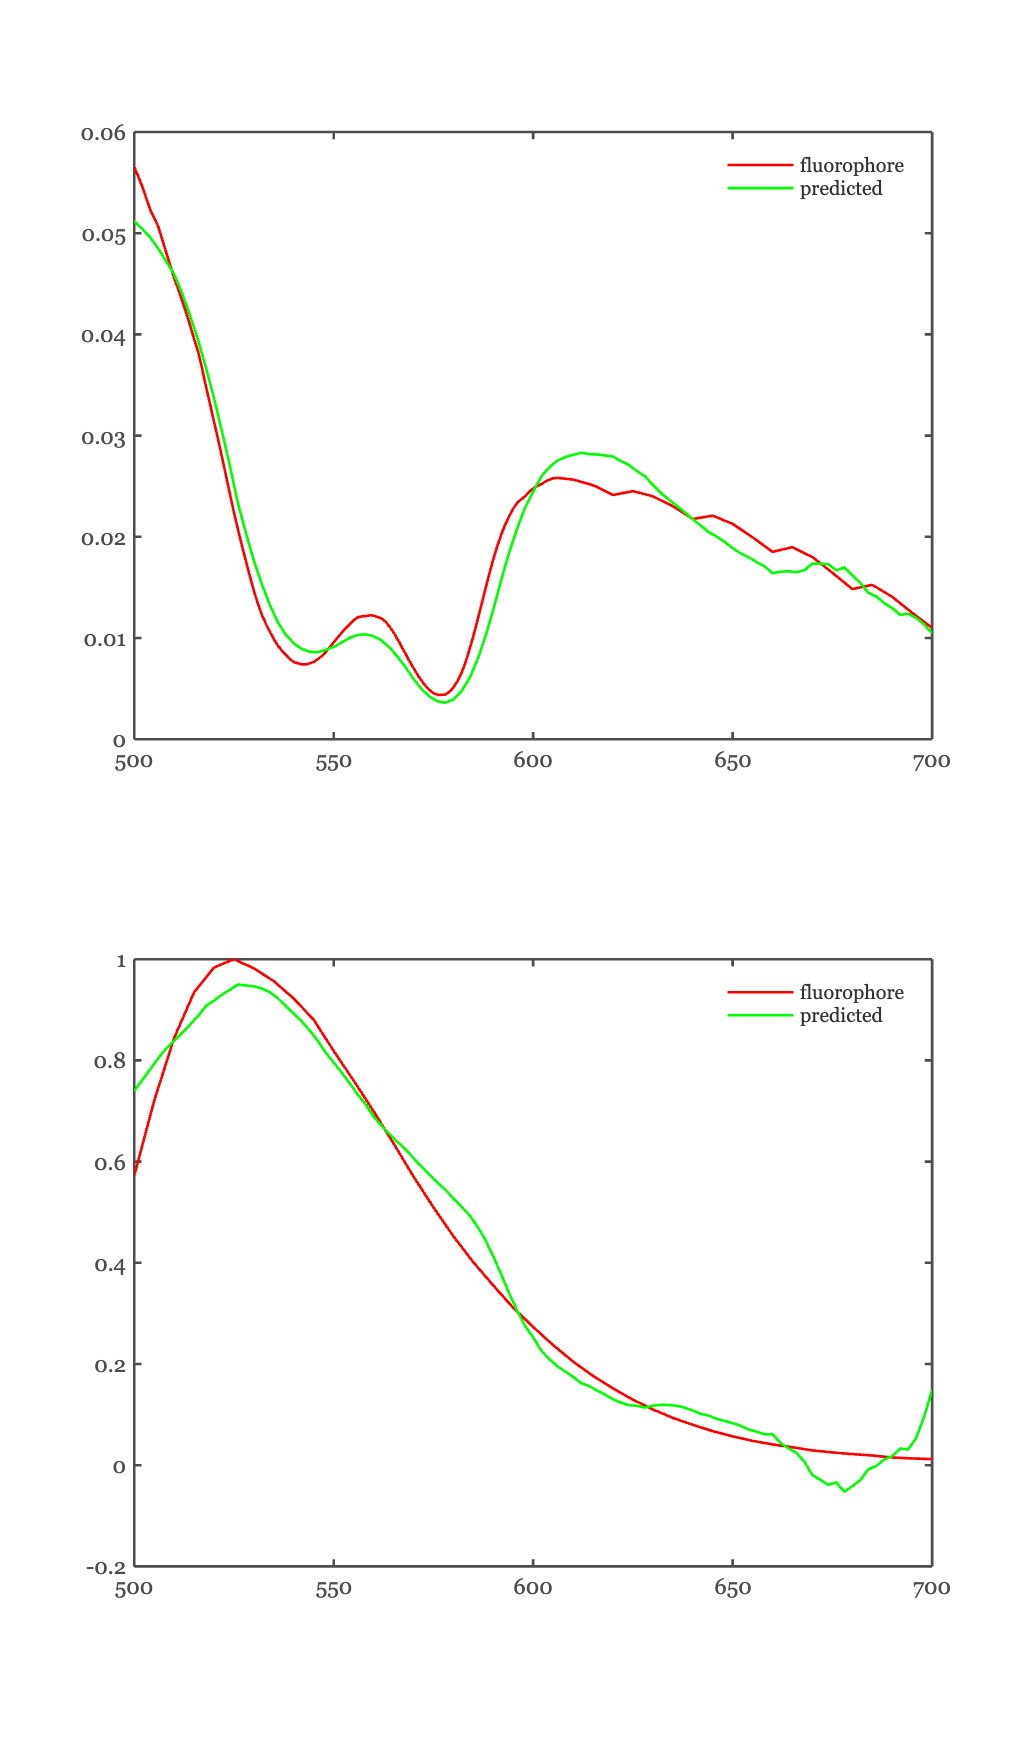

nDim = 3;   % How many PCs to fit the fluorophores?
nFluorophores = 2;
x = UL(:,1:nDim)'*finalFluorophores;
predicted = UL(:,1:nDim)*x;
ieFigure([],'tall');
tiledlayout(nFluorophores,1);
for ii = 1:nFluorophores
    nexttile;
    plot(waves,finalFluorophores(:,ii),waves,predicted(:,ii));
    legend({'fluorophore','predicted'});
end